# Métodos Numéricos ParaEquações Diferenciais Ordinárias / Problemas de Valor Inicial

Atividade/Trabalho 03

Análise Matemática II - Ano Letivo 02022/23

Renato Craveiro | 2018011392 | Lic. ENg. Informática - Regime Pós Laboral

## Introduza os parâmetros para o Problema de Valor Inicial

clear;

strF="t+y";
f=@(t,y) eval(vectorize(strF));

a=0;
b=5;
n=500;
y0=5;

disp('----- Parâmetros para o PVI ----');

----- Parâmetros para o PVI ----


fprintf('f(t,y) = %s | a = %d | b = %d | n = %d | y(0) = %d',strF,a,b,n,y0);

f(t,y) = t+y | a = 0 | b = 5 | n = 500 | y(0) = 5

## Escolha a função a aplicar

try
    yMetodo=NAdamsMoulton(f,a,b,n,y0);
catch me
    warning('Função escrita incorretamente. Verifique se está a escrever uma função em t e y ( f(t,y) )!');
    rethrow(me)    
end

h=(b-a)/n;
t=a:h:b;

syms y(t)
symF = f(t,y);

eqn = diff(y,t) == symF;
ci = y(0) == y0;

sExata = dsolve(eqn,ci);
yExata = @(t)eval(vectorize(sExata));
t = a:((b-a)/n):b;
yExata = yExata(t);
yEuler = NEuler(f,a,b,n,y0);

disp('----- Solução do PVI em modo Gráfico ----')

----- Solução do PVI em modo Gráfico ----


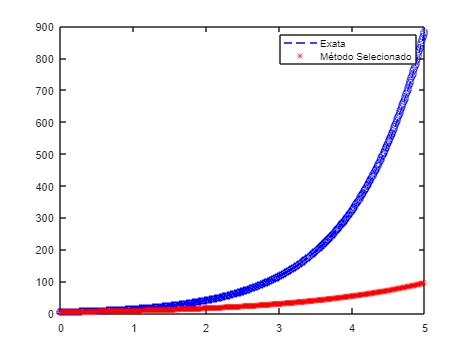


plot(t,yExata,'b--o')
hold on
plot(t,yMetodo,'r*')
hold off
legend('Exata','Método Selecionado')


erroMetodo=abs(yExata-yMetodo);
tabela=[t.', yMetodo.', yExata.', erroMetodo.'];
disp('----- Solução do PVI em modo Tabela de Valores ----')

----- Solução do PVI em modo Tabela de Valores ----


disp ('t | Método Selecionado | Valor Exato | Erro')

t | Método Selecionado | Valor Exato | Erro


disp(tabela)

         0    5.0000    5.0000         0
    0.0100    5.0500    5.0503    0.0003
    0.0200    5.1006    5.1012    0.0006
    0.0300    5.1264    5.1527    0.0264
    0.0400    5.1523    5.2049    0.0525
    0.0500    5.1785    5.2576    0.0791
    0.0600    5.2050    5.3110    0.1060
    0.0700    5.2317    5.3650    0.1334
    0.0800    5.2586    5.4197    0.1611
    0.0900    5.2857    5.4750    0.1893
    0.1000    5.3131    5.5310    0.2179
    0.1100    5.3407    5.5877    0.2470
    0.1200    5.3686    5.6450    0.2764
    0.1300    5.3967    5.7030    0.3063
    0.1400    5.4250    5.7616    0.3367
    0.1500    5.4536    5.8210    0.3674
    0.1600    5.4824    5.8811    0.3987
    0.1700    5.5114    5.9418    0.4304
    0.1800    5.5408    6.0033    0.4626
    0.1900    5.5703    6.0655    0.4952
    0.2000    5.6001    6.1284    0.5283
    0.2100    5.6302    6.1921    0.5619
    0.2200    5.6605    6.2565    0.5960
    0.2300    5.6910    6.3216    0.6306
    0.2400    5.